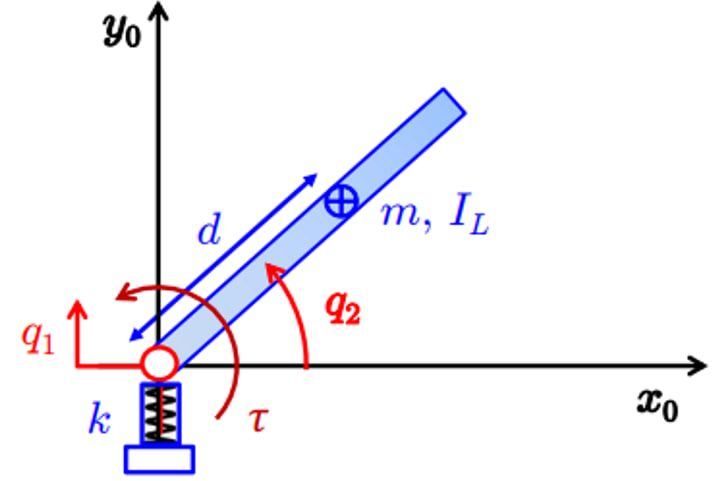

syms q1 q2 q_dot_1 q_dot_2 d K I_L m q_ddot_1 q_ddot_2 tau real

x = d*cos(q2);
y = q1+d*sin(q2);

vx = diff(x,q1)*q_dot_1+diff(x,q2)*q_dot_2;
vy = diff(y,q1)*q_dot_1+diff(y,q2)*q_dot_2;

T = 0.5*m*[vx vy]*[vx; vy;] + 0.5*I_L*q_dot_2^2

$$T = \frac{m\,{\left({\dot{q}}_{1}+d\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}}{2}+\frac{I_{L}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{d^{2}\,m\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);

M = [M11, M12;
     M21, M22;];

M = simplify(M)

$$M = \left(\begin{array}{cc} m & d\,m\,\cos\left(q_{2}\right)\\ d\,m\,\cos\left(q_{2}\right) & m\,d^{2}+I_{L} \end{array}\right)$$


% Coriolis and Centrifugal force
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & -d\,m\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -d\,m\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$



M_subs = subs(M,[q1,q2],[0,0])

$$M\_subs = \left(\begin{array}{cc} m & d\,m\\ d\,m & m\,d^{2}+I_{L} \end{array}\right)$$

M_inv = inv(M_subs)

$$M\_inv = \left(\begin{array}{cc} \frac{m\,d^{2}+I_{L}}{I_{L}\,m} & -\frac{d}{I_{L}}\\ -\frac{d}{I_{L}} & \frac{1}{I_{L}} \end{array}\right)$$

out = M_inv*[0; tau;]

$$out = \left(\begin{array}{c} -\frac{d\,\tau }{I_{L}}\\ \frac{\tau }{I_{L}} \end{array}\right)$$


A = [m*q_ddot_1 + d*m*cos(q2)*q_ddot_2 - d*m*q_dot_2*sin(q2) + K*q1;
    d*m*cos(q2)*q_ddot_1+(m*d^2+I)*q_ddot_2+tau;]

$$A = \left(\begin{array}{c} K\,q_{1}+m\,{\ddot{q}}_{1}+d\,m\,{\ddot{q}}_{2}\,\cos\left(q_{2}\right)-d\,m\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ \tau +{\ddot{q}}_{2}\,\left(m\,d^{2}+\text{I}\right)+d\,m\,{\ddot{q}}_{1}\,\cos\left(q_{2}\right) \end{array}\right)$$


eig_A = simplify(eig(A.'*A))

$$eig\_A = {\left(K\,q_{1}+m\,{\ddot{q}}_{1}+d\,m\,{\ddot{q}}_{2}\,\cos\left(q_{2}\right)-d\,m\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}+{\left(\tau +{\ddot{q}}_{2}\,\left(m\,d^{2}+\text{I}\right)+d\,m\,{\ddot{q}}_{1}\,\cos\left(q_{2}\right)\right)}^{2}$$

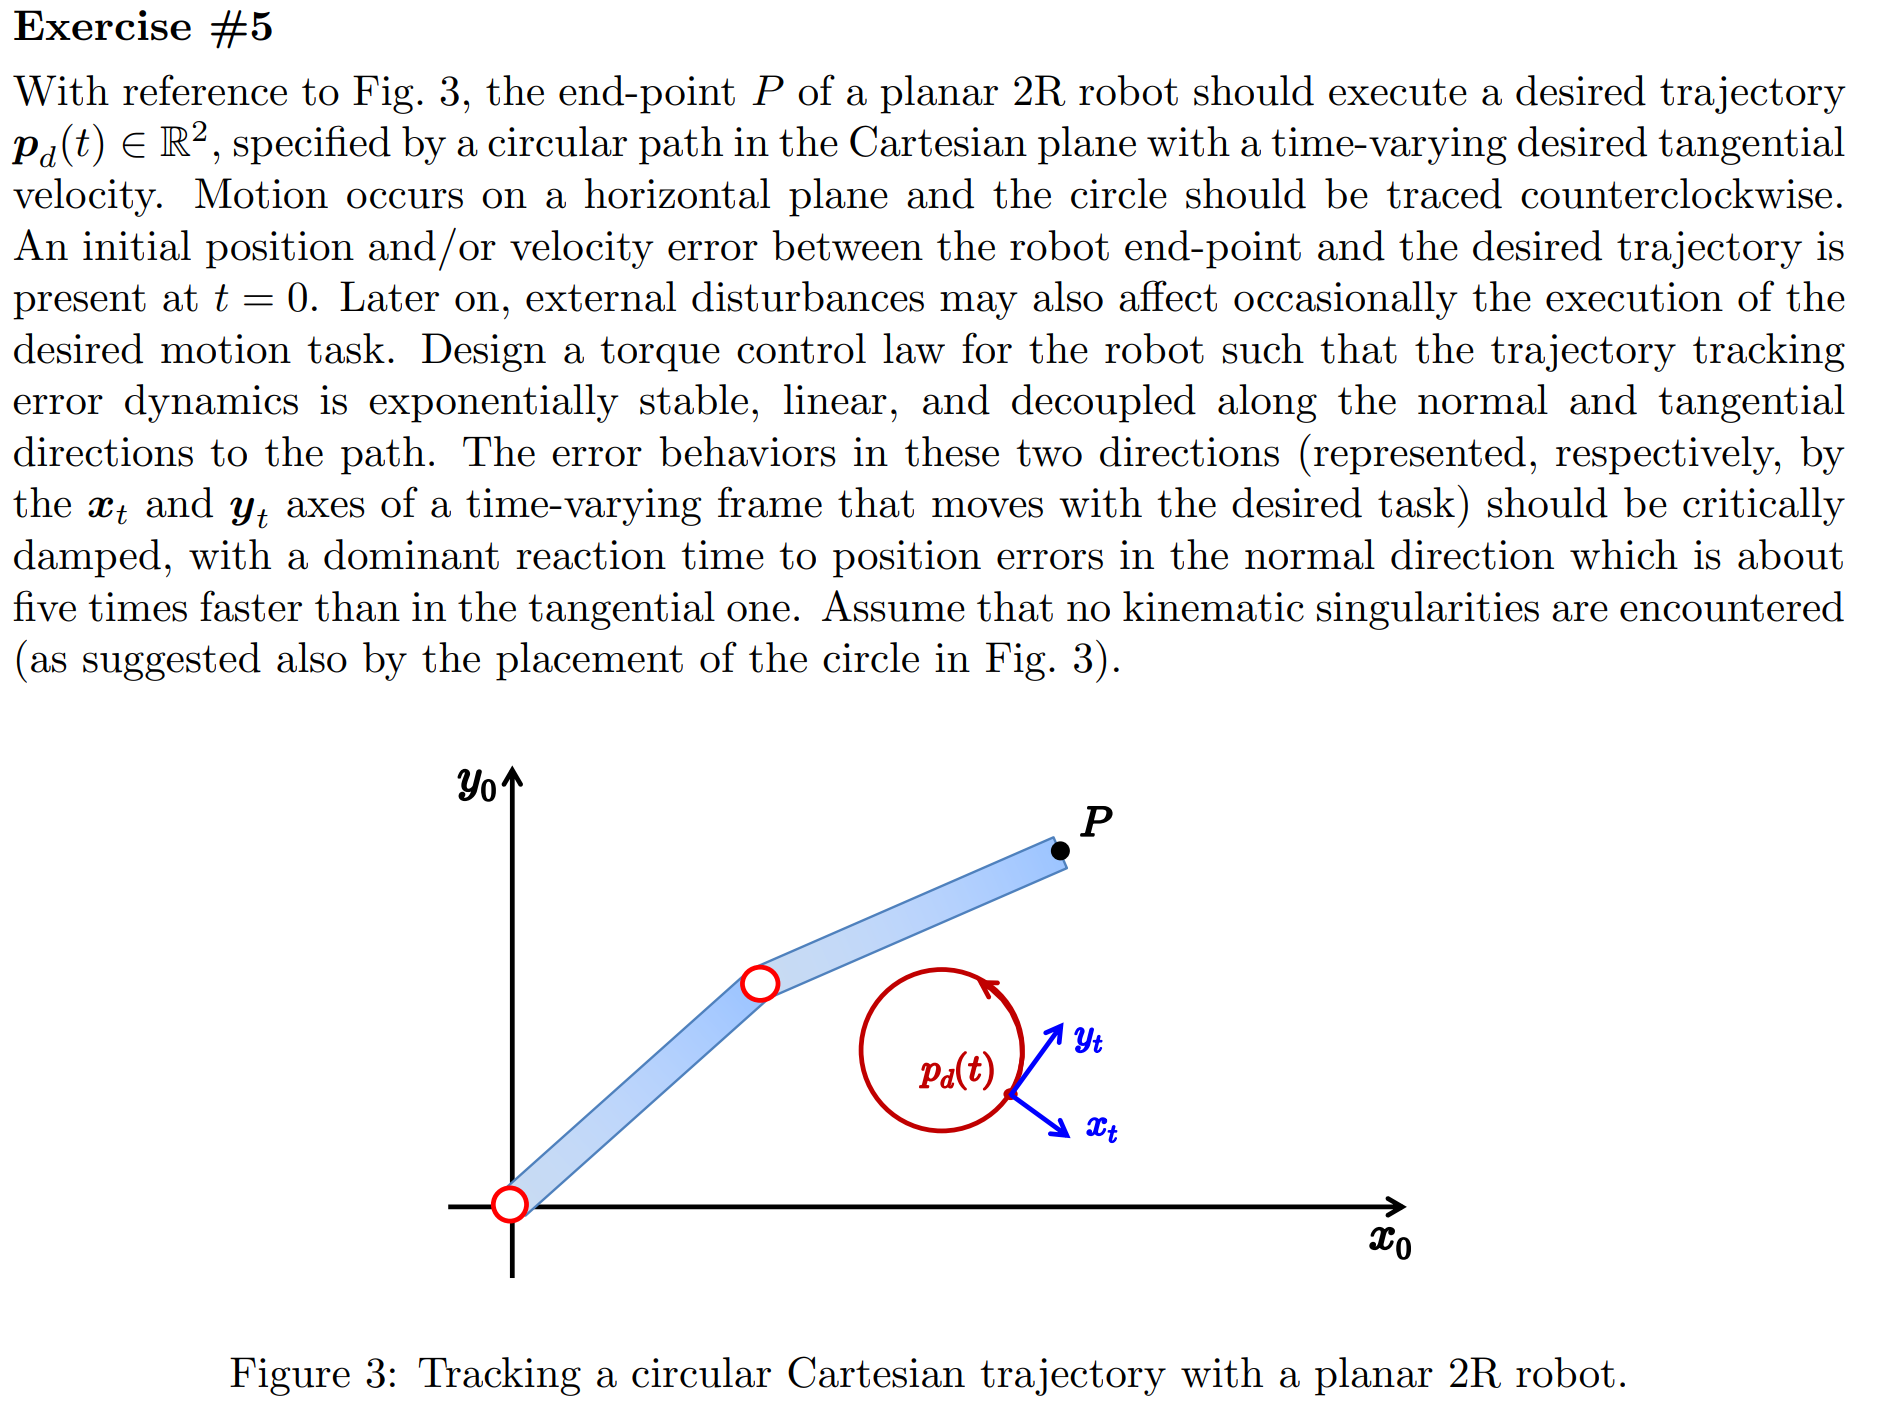

syms q1 q2 q_dot_1 q_dot_2 L_1 L_2 d_1 d_2 I_1 I_2 m_1 m_2 real

x1 = d_1*cos(q1);
y1 = d_1*sin(q1);

vx1 = diff(x1,q1)*q_dot_1+diff(x1,q2)*q_dot_2;
vy1 = diff(y1,q1)*q_dot_1+diff(y1,q2)*q_dot_2;

T1 = 0.5*m_1*[vx1 vy1]*[vx1; vy1;] + 0.5*I_1*q_dot_1^2

$$T1 = \frac{m_{1}\,{d_{1}}^{2}\,{{\dot{q}}_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{m_{1}\,{d_{1}}^{2}\,{{\dot{q}}_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{2}+\frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$


x2 = L_1*cos(q1)+d_2*cos(q1+q2);
y2 = L_1*sin(q1)+d_2*sin(q1+q2);

vx2 = diff(x2,q1)*q_dot_1+diff(x2,q2)*q_dot_2;
vy2 = diff(y2,q1)*q_dot_1+diff(y2,q2)*q_dot_2;

T2 = 0.5*m_2*[vx2 vy2]*[vx2; vy2;] + 0.5*I_2*(q_dot_2+q_dot_1)^2

$$T2 = \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,\cos\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+L_{1}\,\sin\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\right)}^{2}}{2}$$


T = T1+T2

$$T = \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,\cos\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+L_{1}\,\sin\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\right)}^{2}}{2}+\frac{{d_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{{d_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);

M = [M11, M12;
     M21, M22;];

M = simplify(M)

$$M = \left(\begin{array}{cc} m_{2}\,{L_{1}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,L_{1}\,d_{2}+m_{1}\,{d_{1}}^{2}+m_{2}\,{d_{2}}^{2}+I_{1}+I_{2} & m_{2}\,{d_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(q_{2}\right)\,d_{2}+I_{2}\\ m_{2}\,{d_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(q_{2}\right)\,d_{2}+I_{2} & m_{2}\,{d_{2}}^{2}+I_{2} \end{array}\right)$$


% Coriolis and Centrifugal force
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} -L_{1}\,d_{2}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & -L_{1}\,d_{2}\,m_{2}\,\sin\left(q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ L_{1}\,d_{2}\,m_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -L_{1}\,d_{2}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ L_{1}\,d_{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}\right) \end{array}\right)$$


% Direct Kinematics and Jacobian
p = [L_1*cos(q1)+L_2*cos(q1+q2);
     L_1*sin(q1)+L_2*sin(q1+q2);]

$$p = \left(\begin{array}{c} L_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,\cos\left(q_{1}\right)\\ L_{2}\,\sin\left(q_{1}+q_{2}\right)+L_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

J = jacobian(p,[q1,q2])

$$J = \left(\begin{array}{cc} -L_{2}\,\sin\left(q_{1}+q_{2}\right)-L_{1}\,\sin\left(q_{1}\right) & -L_{2}\,\sin\left(q_{1}+q_{2}\right)\\ L_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,\cos\left(q_{1}\right) & L_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$


dp = simplify(J * dq);       % velocità end-effector p_dot
ddp = simplify(jacobian(dp,q)*dq + jacobian(dp,dq)*diff(dq));  % accelerazione

syms q_ddot_1 q_ddot_2 real
ddq = [q_ddot_1; q_ddot_2];
ddp = simplify(jacobian(p, q) * ddq + diff(J, q1)*q_dot_1*dq + diff(J, q2)*q_dot_2*dq)

$$ddp = \begin{array}{l} \left(\begin{array}{c} \left(-\sigma_{2}-L_{1}\,\cos\left(q_{1}\right)\right)\,{{\dot{q}}_{1}}^{2}-2\,L_{2}\,\cos\left(q_{1}+q_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}-L_{2}\,\cos\left(q_{1}+q_{2}\right)\,{{\dot{q}}_{2}}^{2}-{\ddot{q}}_{1}\,\left(\sigma_{1}+L_{1}\,\sin\left(q_{1}\right)\right)-L_{2}\,{\ddot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\\ \left(-\sigma_{1}-L_{1}\,\sin\left(q_{1}\right)\right)\,{{\dot{q}}_{1}}^{2}-2\,L_{2}\,\sin\left(q_{1}+q_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}-L_{2}\,\sin\left(q_{1}+q_{2}\right)\,{{\dot{q}}_{2}}^{2}+{\ddot{q}}_{1}\,\left(\sigma_{2}+L_{1}\,\cos\left(q_{1}\right)\right)+L_{2}\,{\ddot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=L_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}$$


syms p_d1 p_d2 p_d_dot1 p_d_dot2 p_d_ddot1 p_d_ddot2 real
p_d     = [p_d1; p_d2];
dp_d    = [p_d_dot1; p_d_dot2];
ddp_d   = [p_d_ddot1; p_d_ddot2];

e    = simplify(p - p_d);
de   = simplify(dp - dp_d);

% Guadagni tangente/normale
omega_t = 2*pi;   % es. freq tangente
omega_n = 5*omega_t;

Kp = diag([omega_t^2, omega_n^2])

Kp =    39.4784         0
         0  986.9604


Kd = diag([2*omega_t, 2*omega_n])

Kd =    12.5664         0
         0   62.8319



v = simplify(ddp_d - Kp*e - Kd*de);

M_C = simplify(inv(J * inv(M) * J.'));  % Inerzia cartesiana (slide 10)
C_C = sym('C_C', [2,1]);  % oppure calcolalo come J^{-T} * c

tau = simplify(J.' * (M_C * v + C_C))



syms g0 real
% Posizione centri massa
y_c1 = d_1*sin(q1);
y_c2 = L_1*sin(q1) + d_2*sin(q1+q2);
U = m_1*g0*y_c1 + m_2*g0*y_c2

$$U = g_{0}\,m_{2}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+L_{1}\,\sin\left(q_{1}\right)\right)+d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

g_vec = simplify([diff(U,q1); diff(U,q2)])

$$g\_vec = \left(\begin{array}{c} g_{0}\,m_{2}\,\left(d_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,\cos\left(q_{1}\right)\right)+d_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)\\ d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$


tau = simplify(J.' * (M_C * v + C_C) + g_vec)